## Simulate a toy dataset 

Four von Mises Fishers each with 100 data samples 

- four different mus

- the four kappas ranges from 35, 30, 20, 10

init;
mu =[1,0,0; [1,1,1]./sqrt(3); [0,0,1]; [0, -1, -1]./sqrt(2) ];
kappa= [35, 30, 20, 10];
K = 4;
N=400;
pi = [0.25, 0.25, 0.25, 0.25];
ns = pi*N;
tau= kappa;
DAT_SET =[];
for i = 1:length(ns)
    D =vsamp(mu(i,:)', tau(i), ns(i));
    DAT_SET=[DAT_SET ; D];
end
DAT_simple_label = repelem(1:4, [100,100,100,100]);


### Plot the data 

- blue: kappa = 35

- green: kappa = 30

- purple: kappa = 20

- red: kappa = 10

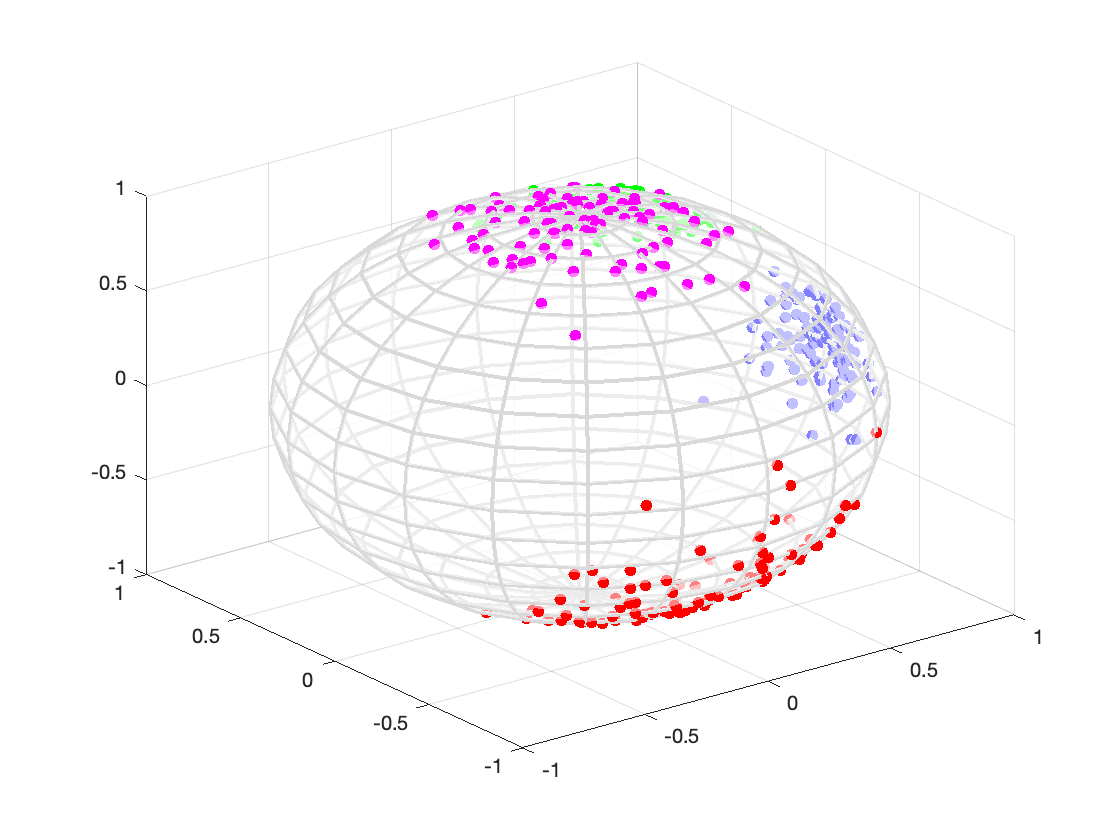

figure;
[x, y,z] = sphere;
tt = scatter3(DAT_SET(1:100,1), DAT_SET(1:100,2), DAT_SET(1:100,3), 'b', 'filled'); hold on;
tt2 = scatter3(DAT_SET(101:200,1), DAT_SET(101:200,2), DAT_SET(101:200,3), 'g', 'filled'); hold on;
tt3 = scatter3(DAT_SET(201:300,1), DAT_SET(201:300,2), DAT_SET(201:300,3), 'm', 'filled'); hold on;
tt4 = scatter3(DAT_SET(301:400,1), DAT_SET(301:400,2), DAT_SET(301:400,3), 'r', 'filled'); hold on;
s1= surf(x, y, z,  'FaceAlpha',0.5, 'facecolor','w','EdgeColor',0.85*[1 1 1], 'linewidth', 2);

### **Bayesian Inference on a singular vMF by Gibbs sampling **

Gibbs sampling on one vMF, sample 100 gibbs iterations/samples 

- the blue one; 

- true mu: [1, 0, 0]

- true kappa: 35

% equivalent to a mixture of 1 vMF 
KK = 1

KK = 1

[~,mus,kappas]=MvMF_inference(DAT_SET(1:100,:), 200, KK);

Iteration: 10.
Iteration: 20.
Iteration: 30.
Iteration: 40.
Iteration: 50.
Iteration: 60.
Iteration: 70.
Iteration: 80.
Iteration: 90.
Iteration: 100.
Iteration: 110.
Iteration: 120.
Iteration: 130.
Iteration: 140.
Iteration: 150.
Iteration: 160.
Iteration: 170.
Iteration: 180.
Iteration: 190.
Iteration: 200.


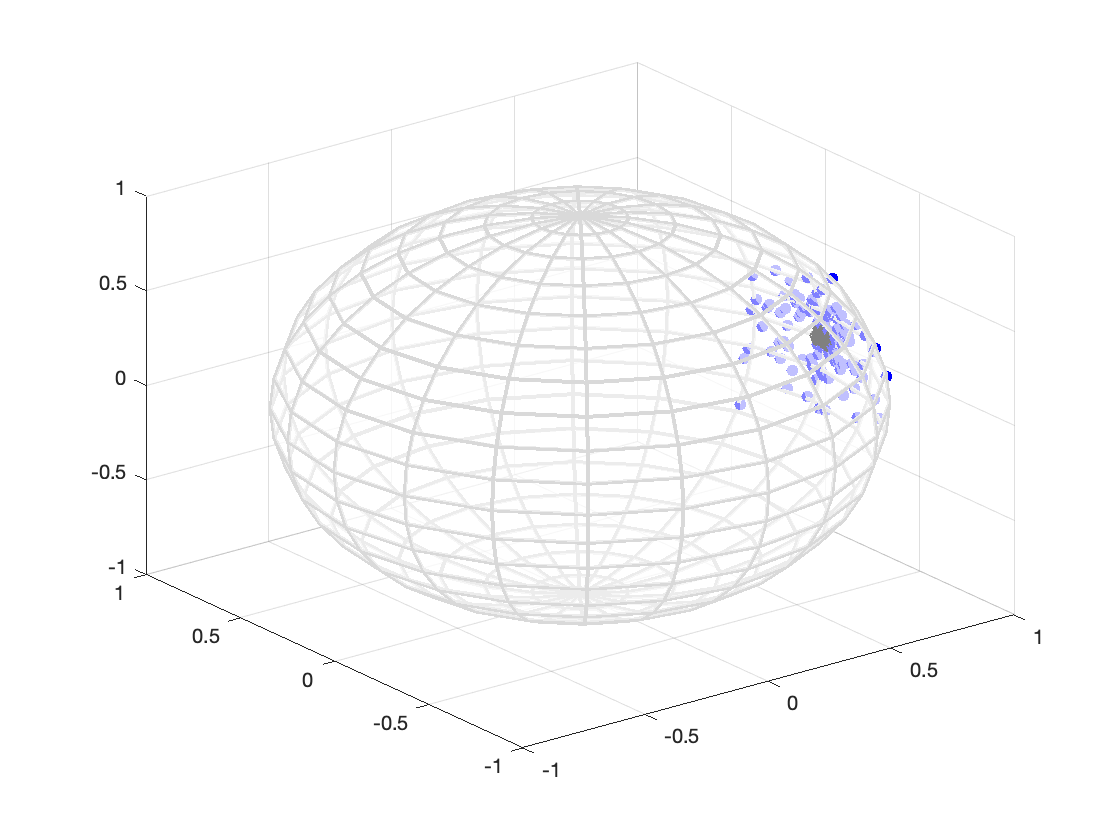

figure;
[x, y,z] = sphere;
mus = squeeze(mus)';
scatter3(DAT_SET(1:100,1), DAT_SET(1:100,2), DAT_SET(1:100,3), 'blue', 'filled'); hold on;
scatter3(mus(:,1), mus(:,2), mus(:,3), 'black', 'filled'); hold on;
surf(x, y, z,  'FaceAlpha',0.5, 'facecolor','w','EdgeColor',0.85*[1 1 1], 'linewidth', 2);

True kappa is 35 

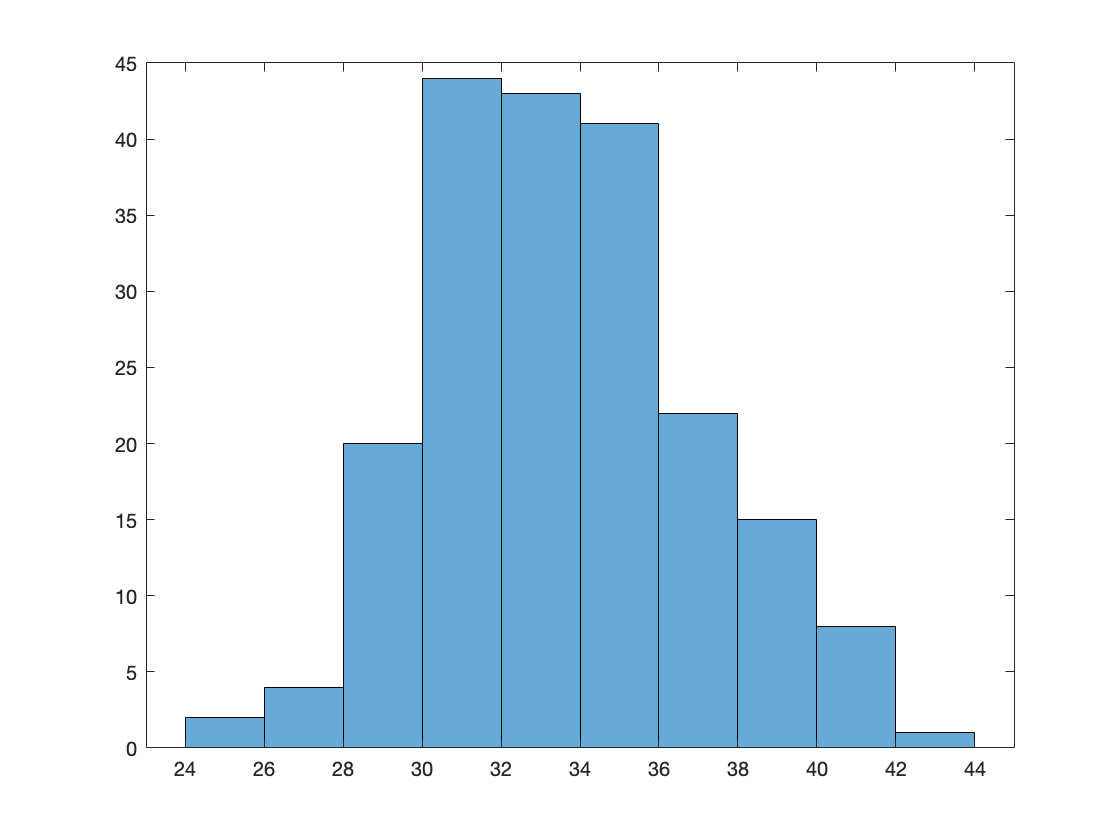

figure;
histogram(kappas);

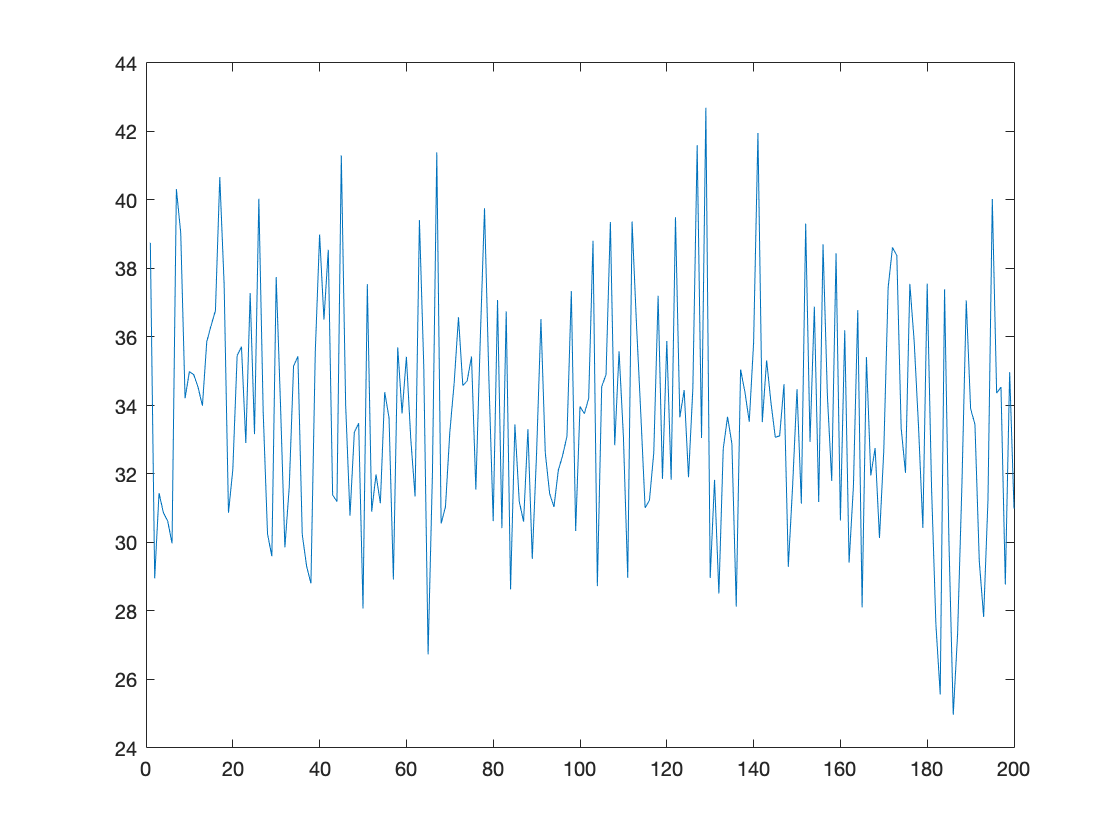

figure;
plot(kappas);

### Bayesian Inference on Mixture of vMFs by Gibbs sampling 

[sm_a,sm_b,sm_c]=MvMF_inference(DAT_SET, 150, 4);

Iteration: 10.
Iteration: 20.
Iteration: 30.
Iteration: 40.
Iteration: 50.
Iteration: 60.
Iteration: 70.
Iteration: 80.
Iteration: 90.
Iteration: 100.
Iteration: 110.
Iteration: 120.
Iteration: 130.
Iteration: 140.
Iteration: 150.


The posterior sample of the mu are:

post_mus=mean(sm_b(:,:, 50:150),3)

post_mus =     0.6087    0.5954    0.5237
    0.0321    0.0185    0.9988
    0.0025   -0.7220   -0.6906
    0.9995    0.0046    0.0155


Ground truth are :

mu

mu =     1.0000         0         0
    0.5774    0.5774    0.5774
         0         0    1.0000
         0   -0.7071   -0.7071


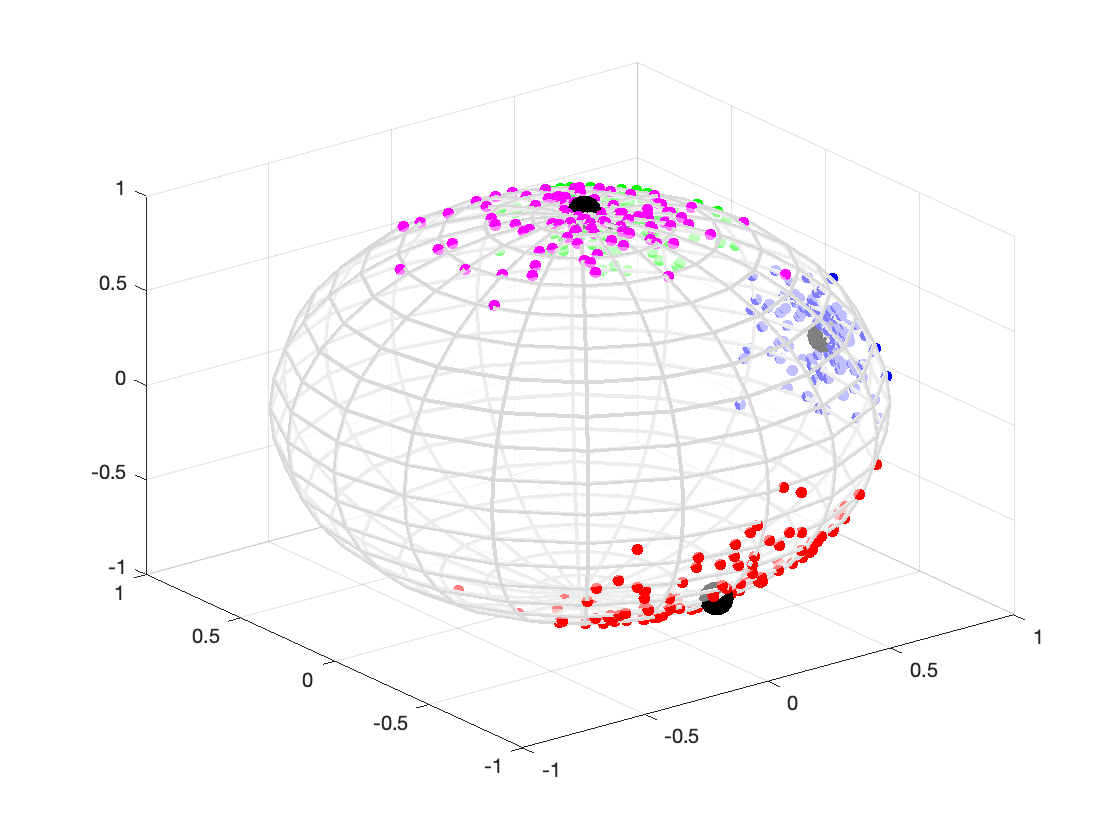


figure;
[x, y,z] = sphere;
tt = scatter3(DAT_SET(1:100,1), DAT_SET(1:100,2), DAT_SET(1:100,3), 'b', 'filled'); hold on;
tt2 = scatter3(DAT_SET(101:200,1), DAT_SET(101:200,2), DAT_SET(101:200,3), 'g', 'filled'); hold on;
tt3 = scatter3(DAT_SET(201:300,1), DAT_SET(201:300,2), DAT_SET(201:300,3), 'm', 'filled'); hold on;
tt4 = scatter3(DAT_SET(301:400,1), DAT_SET(301:400,2), DAT_SET(301:400,3), 'r', 'filled'); hold on;
mm = scatter3(post_mus(:,1), post_mus(:,2), post_mus(:,3), 300, 'black', 'filled'); hold on;
s1= surf(x, y, z,  'FaceAlpha',0.5, 'facecolor','w','EdgeColor',0.85*[1 1 1], 'linewidth', 2);

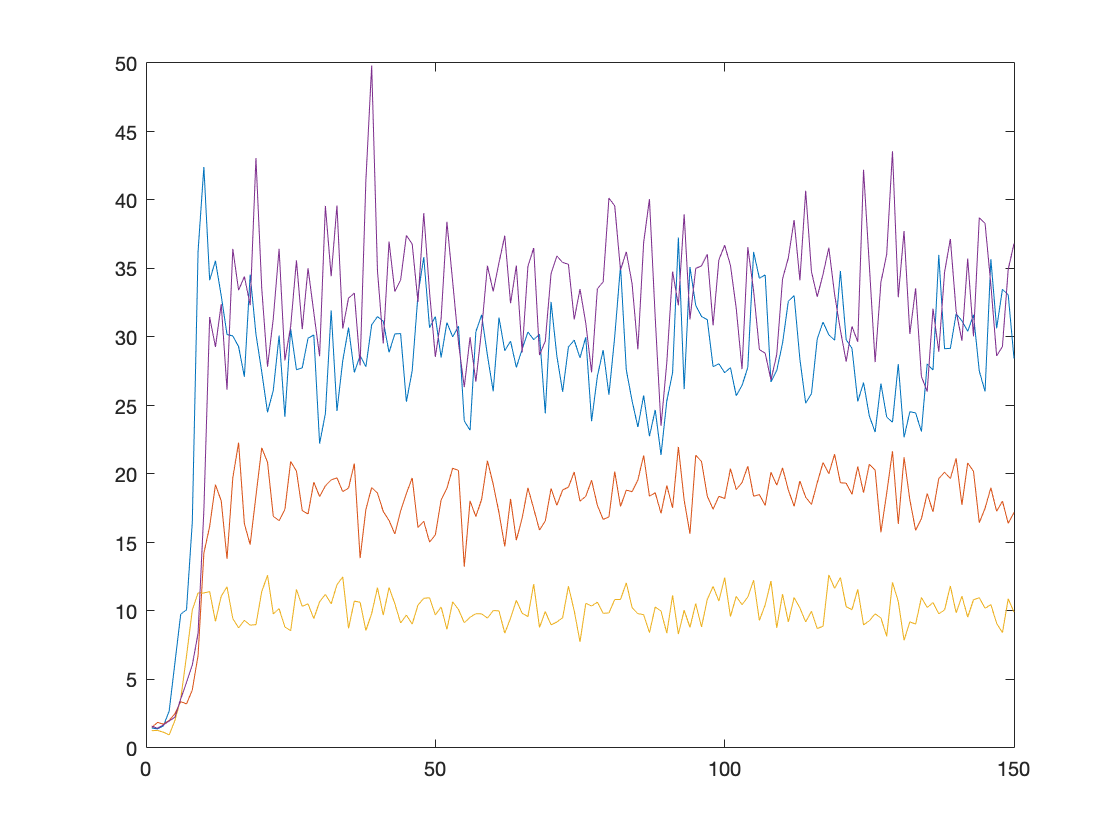

figure;
plot(sm_c');

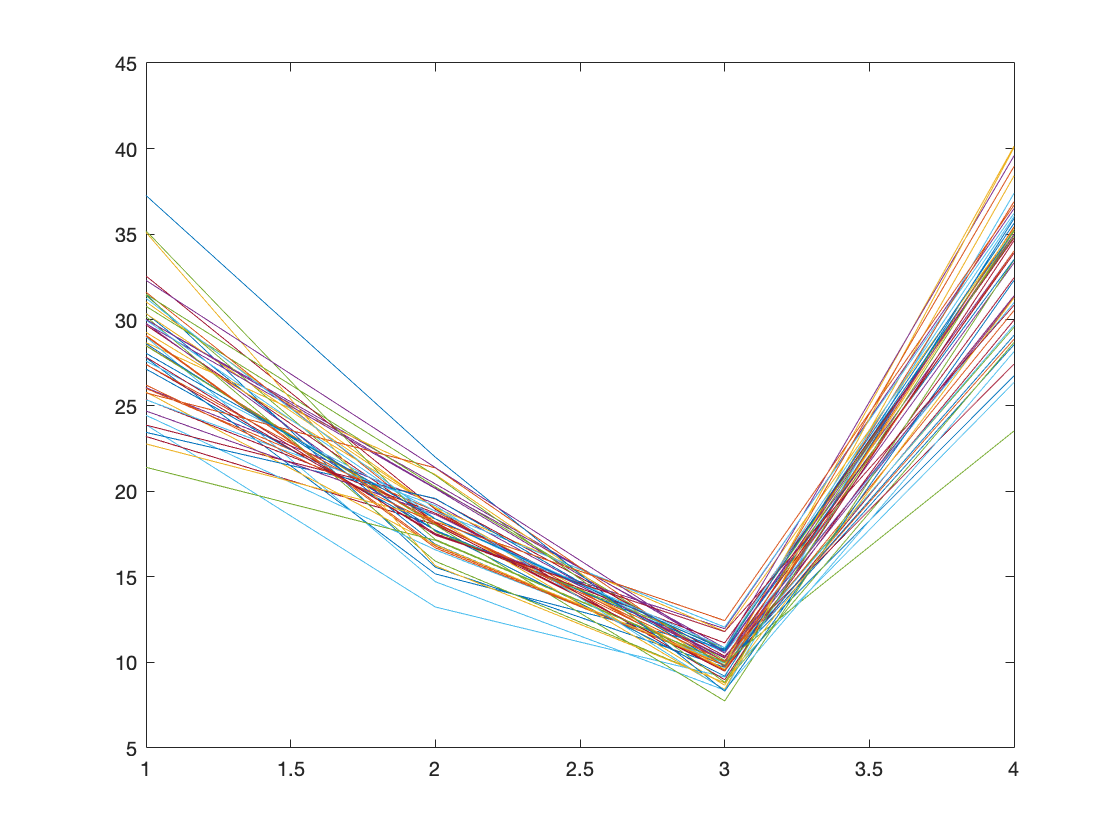

figure;
plot(sm_c(:,50:100));

#### We can also check whether the clustering results by check normalised mutual information against the true labels 

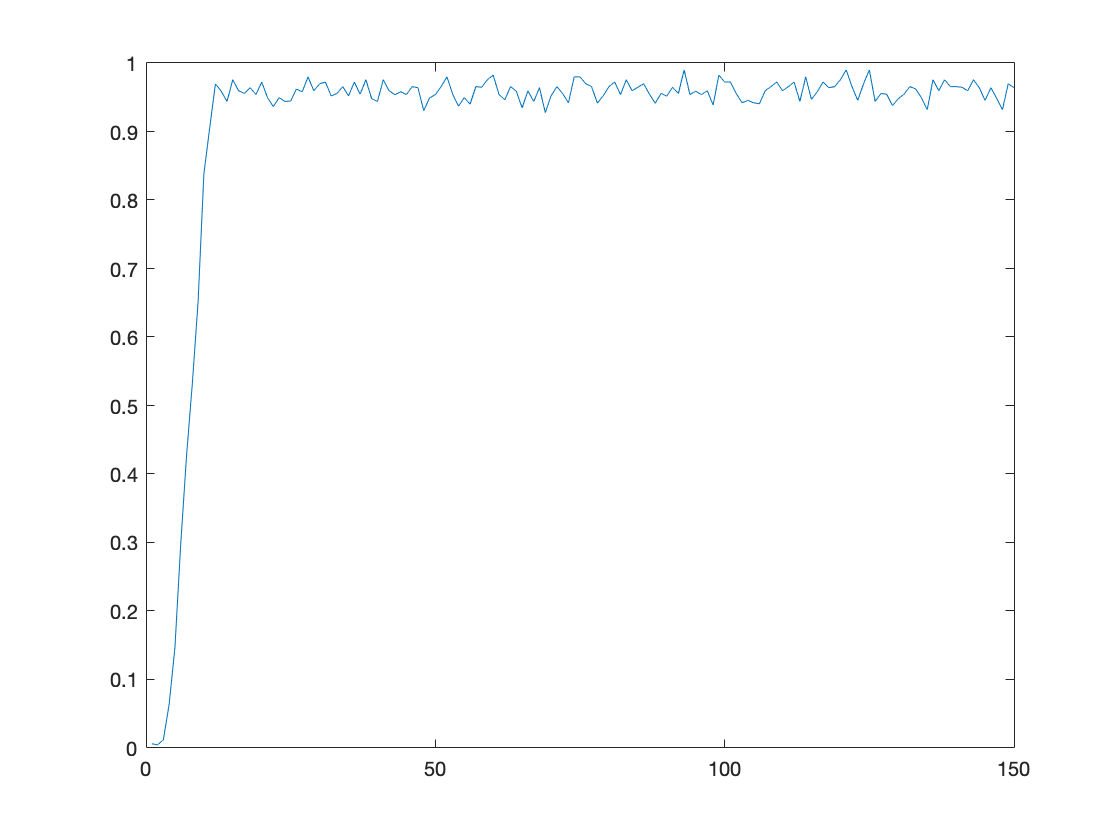

[ks_, nmi_s_, ~, ~, ~, ~]=analyse_sample(sm_a, DAT_simple_label, false);
figure;
plot(nmi_s_);

## Dirichlet process mixture inference

now we apply infinite mixture model to the data set 

[tmp_spl, tmp_ll]=iMvMF_inference(DAT_SET, 400, true);

Iteration: 100.
Iteration: 200.
Iteration: 300.
Iteration: 400.


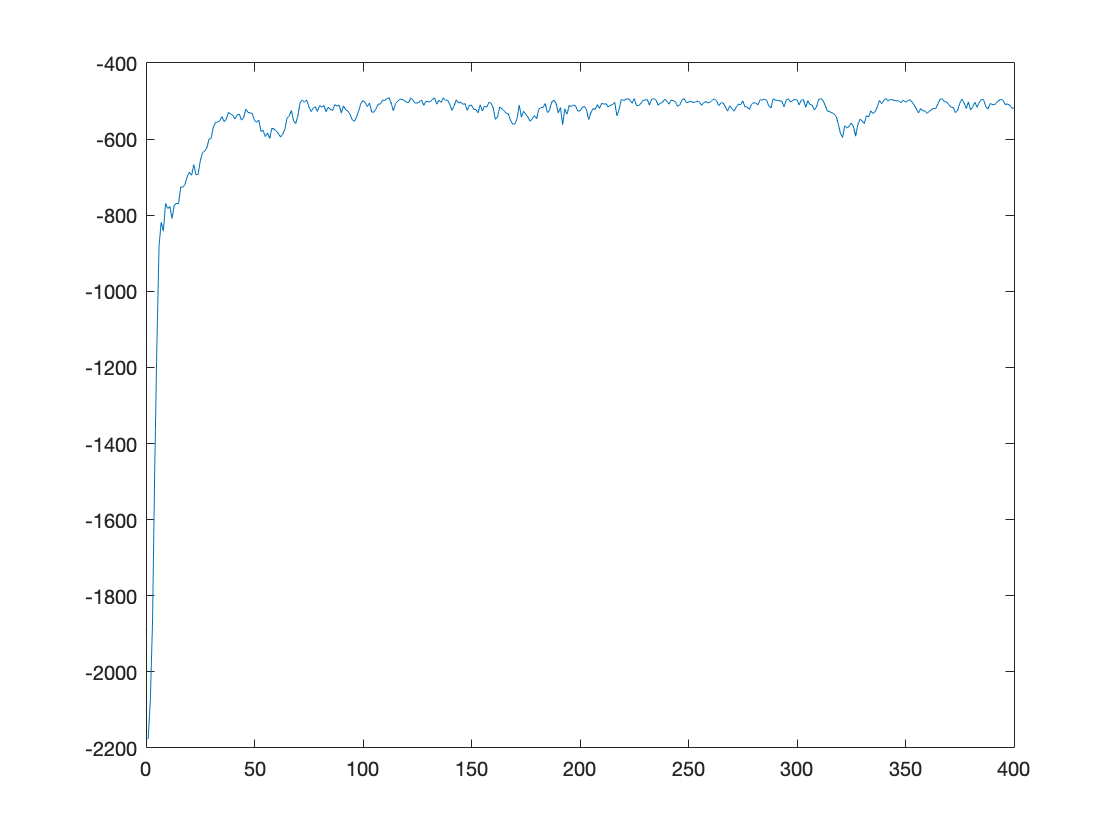

plot(tmp_ll);

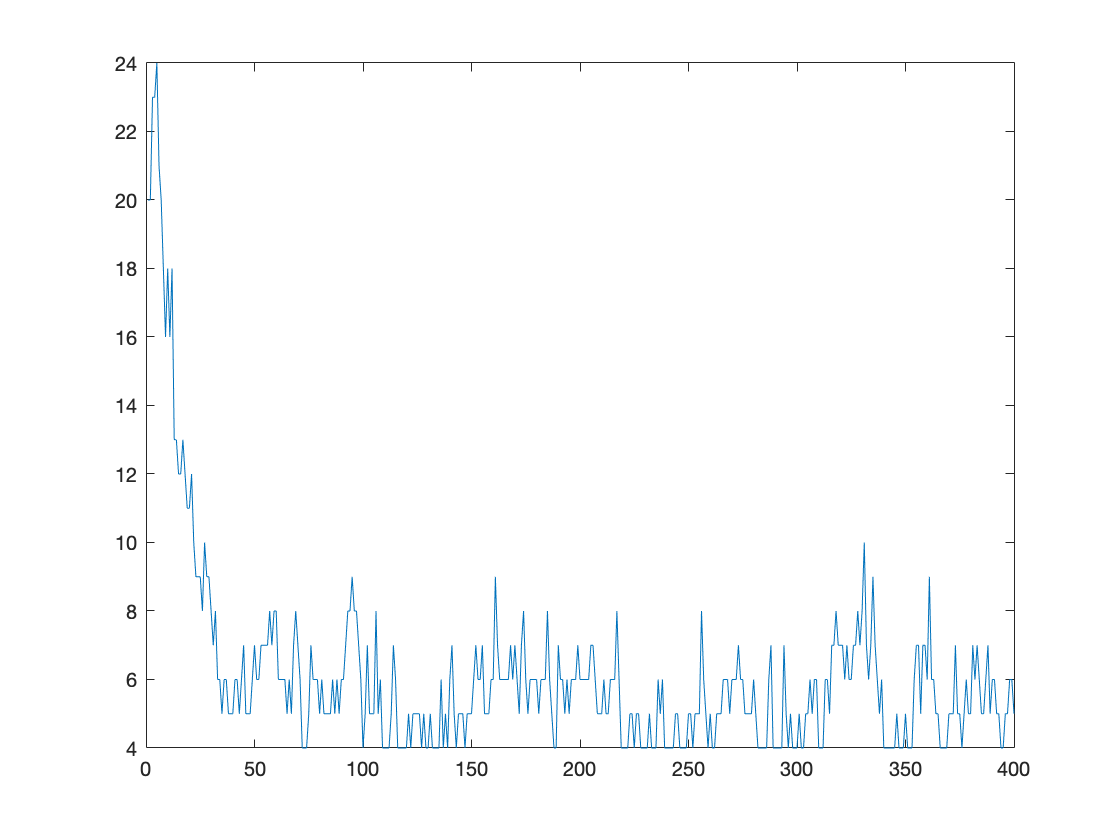

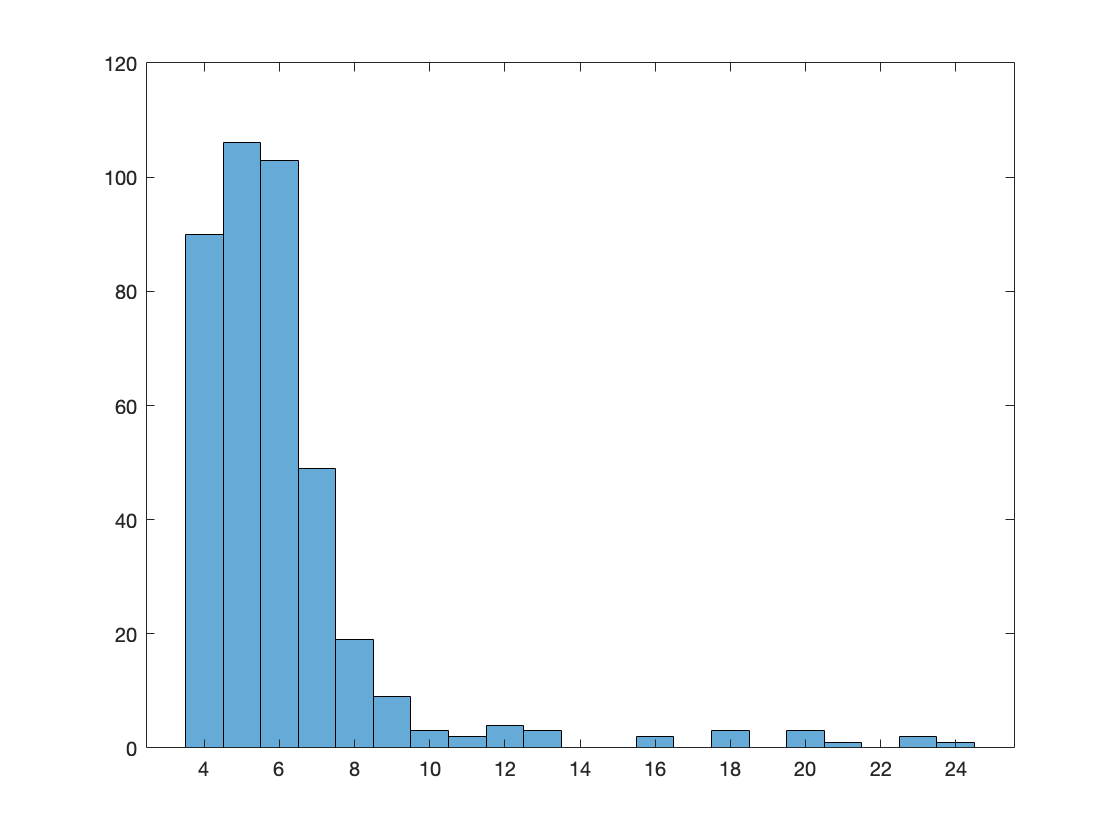

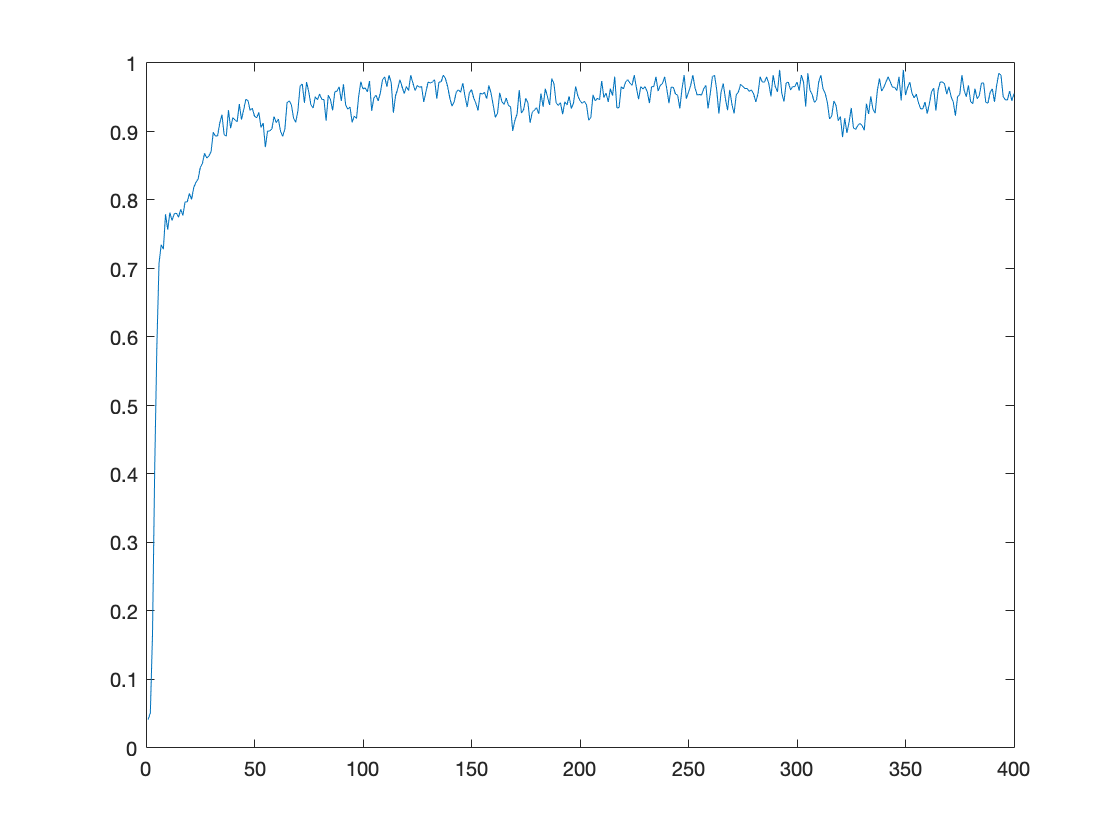

[ks_, nmi_s_, ~, ~, ~, ~]=analyse_sample(tmp_spl, DAT_simple_label, true);

We can also run inifnite mixture on singular vMF to see whether they can find it 

[ks_spl, ll_spl]=iMvMF_inference(DAT_SET(1:100,:), 500, true);

Iteration: 100.
Iteration: 200.
Iteration: 300.
Iteration: 400.
Iteration: 500.


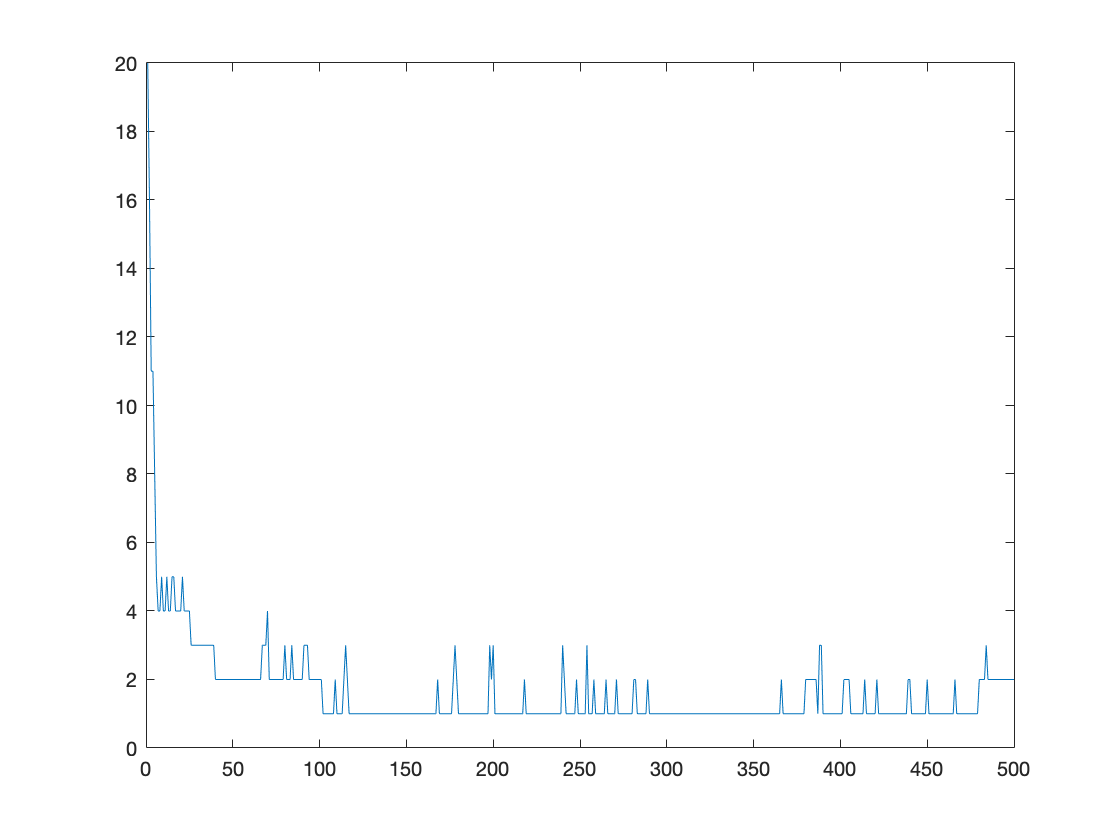

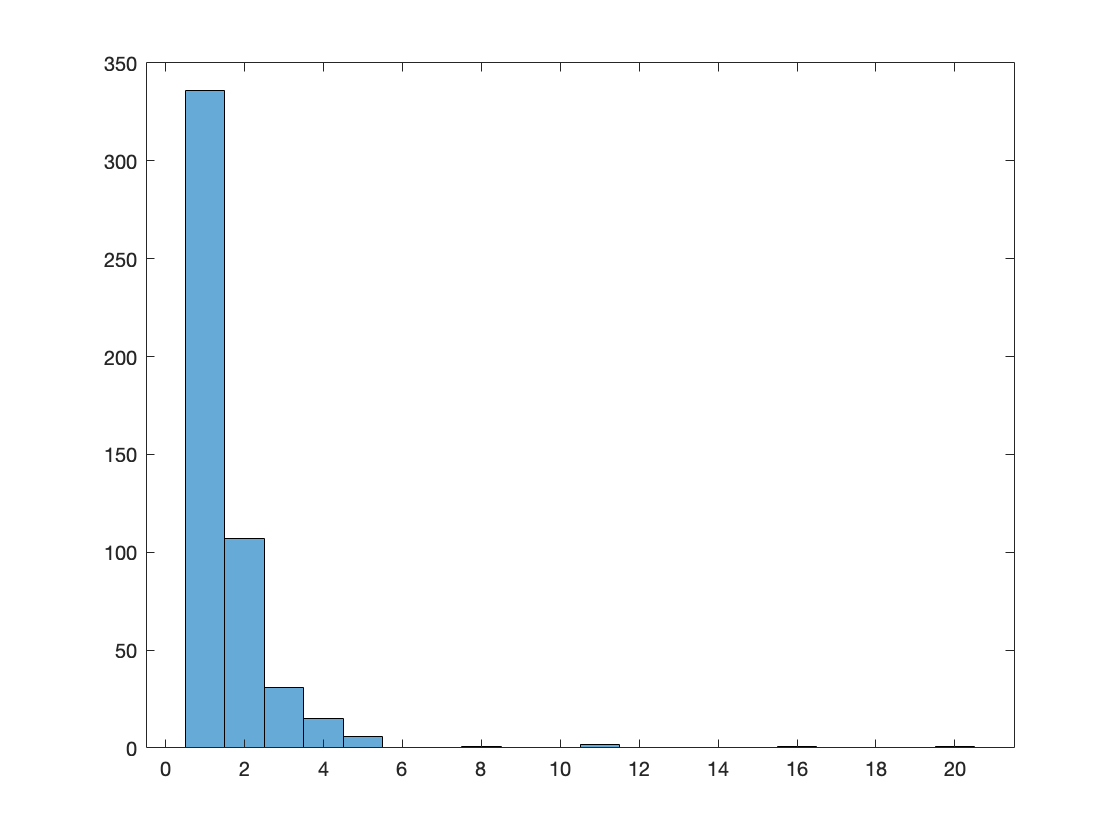

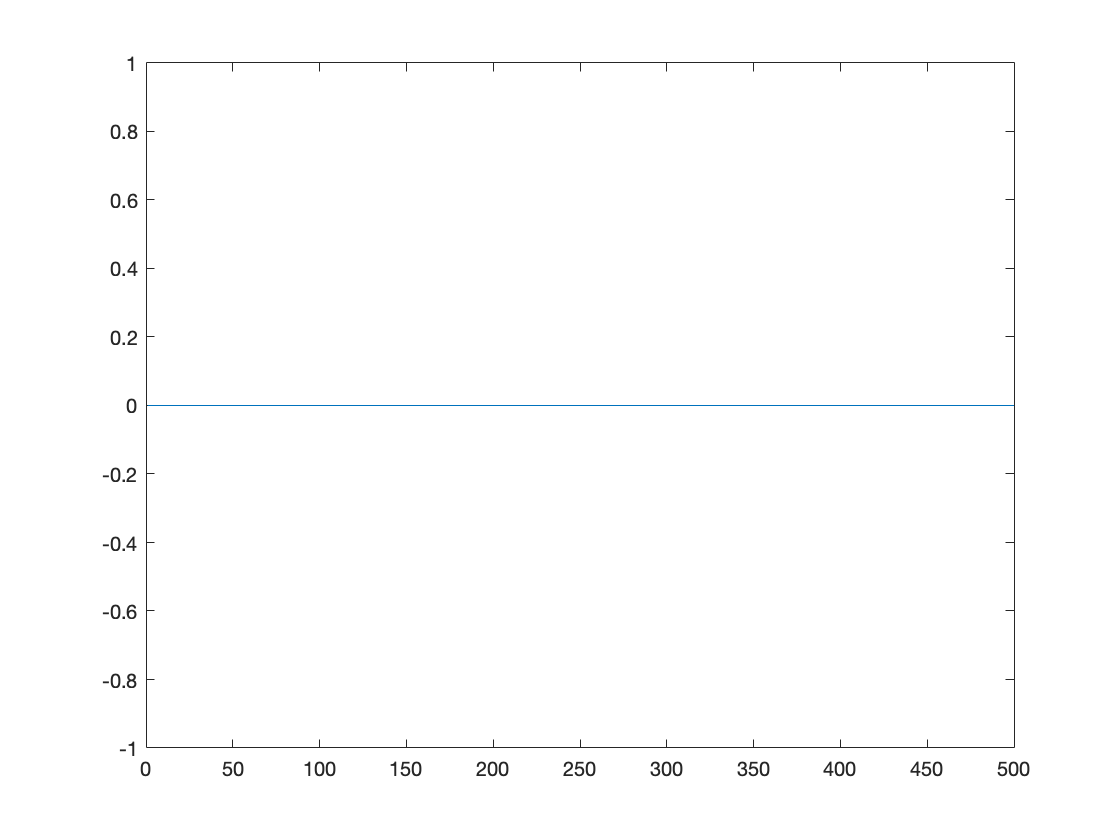

[ks_, nmi_s_, ~, ~, ~, ~]=analyse_sample(ks_spl, DAT_simple_label(1:100), true);

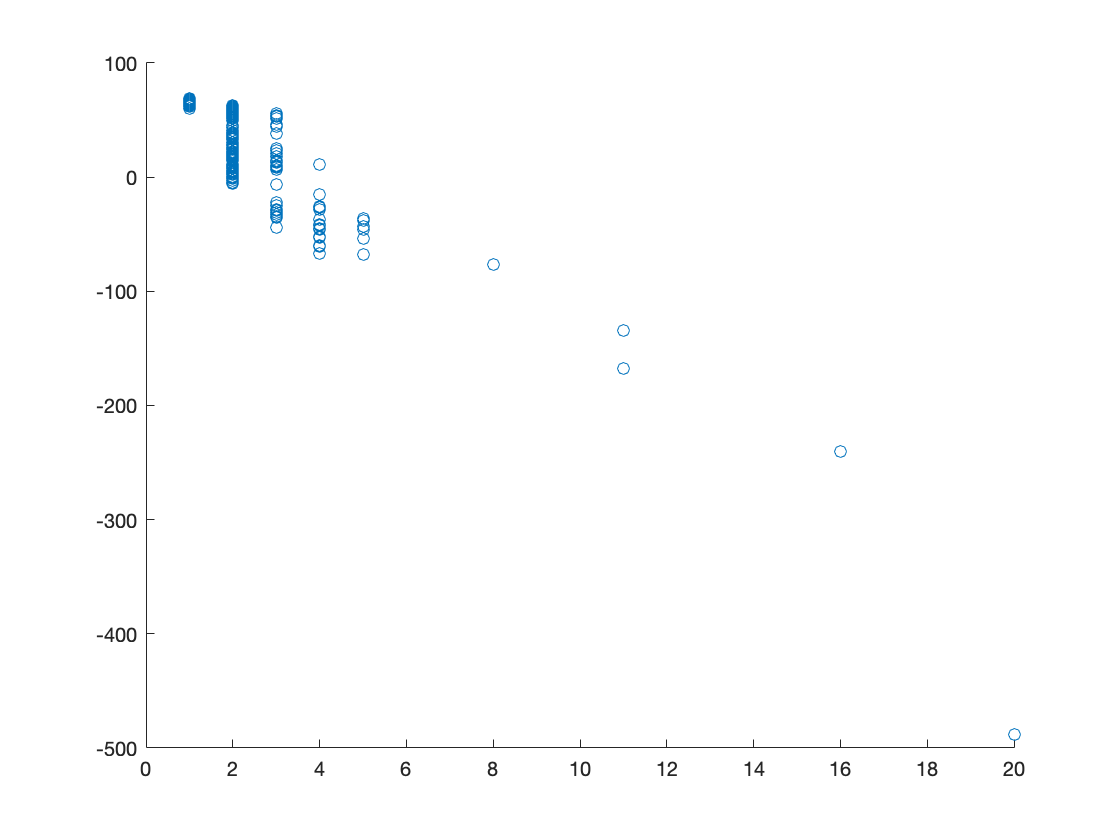

scatter(ks_, ll_spl)

[ks, tmpll_new, ~]=Collapsed_iMvMF_inference(DAT_SET, 500, true, true);

Iteration: 100.
Iteration: 200.
Iteration: 300.
Iteration: 400.
Iteration: 500.


[ks_, nmi_s_, ~, ~, ~, ~]=analyse_sample(ks, DAT_simple_label, true);